# Getting 

## Introduction

tbd

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

j_vector = [1 2 4];
l_vector = [1 2 4];


% mVARboptions

% linsys_solving_method = 'mldivide';
linsys_solving_method = 'lsqlin';

% get_VAR_eqs_steps       = '2-steps';
get_VAR_eqs_steps       = '1-step';

% impose_BBT = 'none';
impose_BBT = 'symmetric';

linsys_B_matrix = 'ext';
% linsys_B_matrix = 'iter';


log_write = 1;
log_name  = 'my_log';
log_path  = '~/Escritorio/';


Nf = 100;

CC              = colororder;
color_input     = CC(1,:);
color_estimated = CC(3,:);
linewidth       = 2;
font_size       = 14;
figure_position = [0 0 1000 800];
M_max_plot      = 30;

load dataset_02_VAR_2V.mat CMF_VAR

CMF_input = CMF_VAR;
clear CMF_VAR;

M = CMF_input.x_parameters.M;






mVARboptions = initialise_mVARboptions();
mVARboptions = fun_append_mVARboptions(mVARboptions,...
                                       'linsys_solving_method',linsys_solving_method,...
                                       'get_VAR_eqs_steps',get_VAR_eqs_steps,...
                                       'impose_BBT',impose_BBT,...
                                       'linsys_B_matrix',linsys_B_matrix,...
                                       'log_write',log_write,...
                                       'log_name',log_name,...
                                       'log_path',log_path);



### Case


VAR_estimated = initialise_VAR('j_vector',j_vector);

VAR_estimated = get_VAR_CMF(CMF_input, VAR_estimated, l_vector, mVARboptions);

Solved 0 variables, 0 equality, and 2 inequality constraints during the presolve.

 Iter         Resnorm  Primal Infeas    Dual Infeas  Complementarity  
    0    7.033874e-01   4.163336e-17   6.169026e-01     1.000000e+00  
    1    2.741629e-01   0.000000e+00   3.084513e-04     2.200872e-01  
    2    4.918606e-02   1.214306e-17   1.542257e-07     5.407563e-02  
    3    6.093405e-03   2.602085e-18   3.715262e-08     1.258842e-02  
    4    3.350823e-04   4.336809e-19   1.616738e-08     2.382974e-03  
    5    3.072311e-06   1.897354e-18   4.919224e-09     2.211657e-04  
    6    5.405472e-10   8.221514e-20   5.612781e-10     2.961117e-06  
    7    1.332268e-15   1.017148e-21   7.963630e-12     2.018985e-09  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


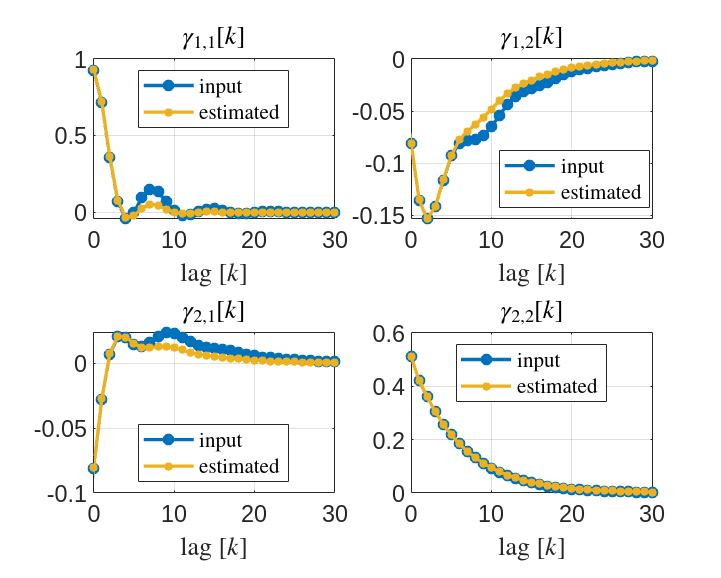


CMF_estimated = initialise_CMF('M',M);

CMF_estimated = get_CMF_VAR(VAR_estimated, CMF_estimated, mVARboptions);





% Plot

figure


for ii=1:2

    for jj=1:2

        subplot(2,2,jj+2*(ii-1))

        x = CMF_input.xlag_values;
        y = squeeze(CMF_input.y_values(ii,jj,:));
        plot(x,y,'O-','color',color_input,'MarkerFaceColor',color_input,...
                      'LineWidth',linewidth,'markersize',5)
        hold on
        x = CMF_estimated.xlag_values;
        y = squeeze(CMF_estimated.y_values(ii,jj,:));
        plot(x,y,'O-','color',color_estimated,'MarkerFaceColor',color_estimated,...
                      'LineWidth',linewidth,'markersize',3)
        title(sprintf('$\\gamma_{%d,%d}[k]$',ii,jj),'Interpreter','latex')
        legend({'input','estimated'},...
                'Interpreter','latex','location','best')
        grid on
        xlim([0 M_max_plot])
        xlabel('lag [$k$]','Interpreter','latex')

        set(gca,'fontsize',font_size)

    end

end

set(gcf,'position',figure_position)

## Remarks

- tbd